clc
close all
clear all
cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../../exp/tartanair_full_semantic/';
currentfolder = 'tartanair_toy_exp_50_0.5/'

currentfolder = 'tartanair_toy_exp_50_0.5/'

index = 2

index = 2

index_s = int2str(index)

index_s = '2'

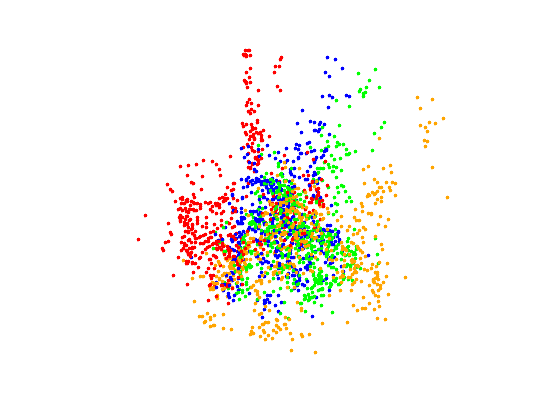

V1 = pcread(append(rootfolder,currentfolder,index_s,'/0normal.pcd'))';
V2 = pcread(append(rootfolder,currentfolder,index_s,'/1normal.pcd'))';
V3 = pcread(append(rootfolder,currentfolder,index_s,'/2normal.pcd'))';
V4 = pcread(append(rootfolder,currentfolder,index_s,'/3normal.pcd'))';
V = {V1,V2,V3,V4}';
figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};

figure(2) 
hold on
for i=1:4
    pointscolor=uint8(zeros(V{i}.Count,3));
    pointscolor(:,1)=colormap{i}(1);
    pointscolor(:,2)=colormap{i}(2);
    pointscolor(:,3)=colormap{i}(3);
    V{i}.Color=pointscolor;
    pcshow(V{i},'MarkerSize', 70);
    set(gcf, 'color','w')
    
    
    view([-30.4 3.6])
end
hold off

## color ICP result

cla
gtfilename = append(rootfolder,currentfolder,index_s,'/color_icp.txt')

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_50_0.5/2/color_icp.txt'

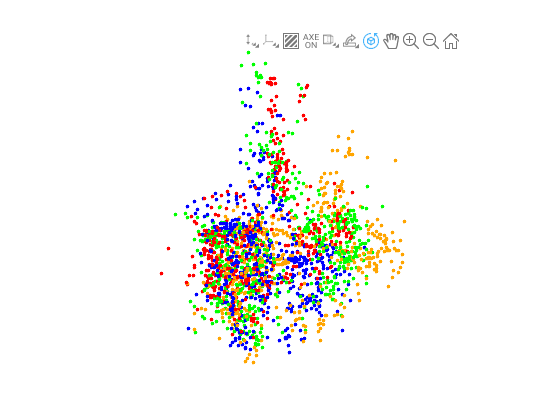

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
figure(3)
hold on
for i=1:4
    T = Tcvo{i};
    transform_p = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
    
    ptCloudOut = pointCloud(transform_p);
    ptCloudOut.Color = V{i}.Color;
    pcshow(ptCloudOut,'MarkerSize', 70);
     view([-30.4 3.6])
    set(gcf, 'color','w')
end
hold off

## Read cvo pose and do transformation

cla
gtfilename = append(rootfolder,currentfolder,index_s,'/rkhs_intencity_result.txt')

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_50_0.5/2/rkhs_intencity_result.txt'

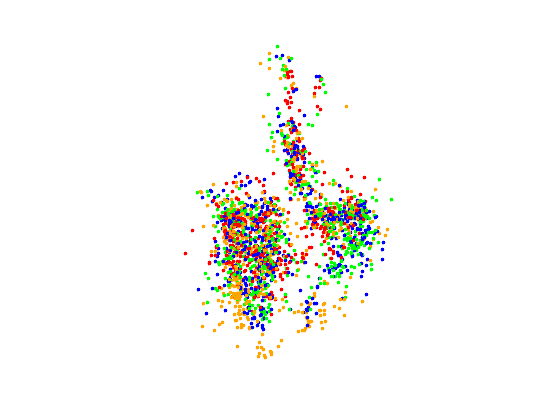

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
figure(3)
hold on
for i=1:4
    T = Tcvo{i};
    transform_p = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
    ptCloudOut = V{i};
    ptCloudOut = pointCloud(transform_p);
    ptCloudOut.Color = V{i}.Color;
    pcshow(ptCloudOut,'MarkerSize', 70);
   view([-30.4 3.6])
    set(gcf, 'color','w')
end
hold off

## Read jrmpc pose and do transformation

cla
gtfilename = append(rootfolder,currentfolder,index_s,['/jrmpc.txt'])

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_50_0.5/2/jrmpc.txt'

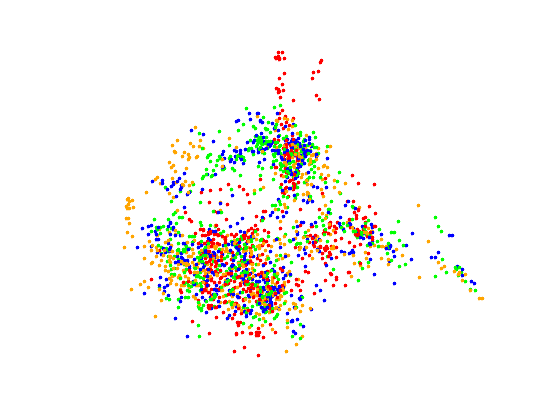

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
figure(3)
hold on
for i=1:4
    T = Tcvo{i};
    transform_p = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
    ptCloudOut = V{i};
    ptCloudOut = pointCloud(transform_p);
    ptCloudOut.Color = V{i}.Color;
    pcshow(ptCloudOut,'MarkerSize', 70);
    view([-30.4 3.6])
    set(gcf, 'color','w')
end
hold off

## Original bunny


cla
rootfolder = '../../exp/tartanair_full_semantic/';
currentfolder = 'tartanair_toy_exp_12.5_0.0/'

currentfolder = 'tartanair_toy_exp_12.5_0.0/'

index = 0

index = 0

index_s = int2str(index)

index_s = '0'

V1 = pcread(append(rootfolder,currentfolder,index_s,'/0normal.pcd'))';
V2 = pcread(append(rootfolder,currentfolder,index_s,'/1normal.pcd'))';
V3 = pcread(append(rootfolder,currentfolder,index_s,'/2normal.pcd'))';
V4 = pcread(append(rootfolder,currentfolder,index_s,'/3normal.pcd'))';
V = {V1,V2,V3,V4}';
figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};


gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../../exp/tartanair_full_semantic/tartanair_toy_exp_12.5_0.0/0/gt_poses.txt'

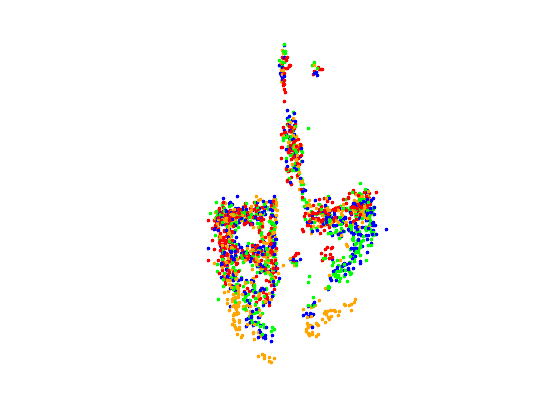

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
for i=1:4
    Tcvo{i} = inv(Tcvo{i});
end
figure(7)
hold on
for i=1:4
    T = Tcvo{i};
    transform_p = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
    pointscolor=uint8(zeros(V{i}.Count,3));
    pointscolor(:,1)=colormap{i}(1);
    pointscolor(:,2)=colormap{i}(2);
    pointscolor(:,3)=colormap{i}(3);
   
    ptCloudOut = V{i};
    ptCloudOut = pointCloud(transform_p);
    ptCloudOut.Color = pointscolor;
    pcshow(ptCloudOut,'MarkerSize', 70);
   view([-30.4 3.6])
    set(gcf, 'color','w')
end
hold off